# Multiple Beams Example

This example shows how multiple beams can be added together.  This live script complements the `examples/multiple_beams.m` scripts, both describe approximately the same functionality.

There are a couple of ways to add beams together:

- Incoherently: the beam coefficients are not added together, instead the force is calculated separately for each beam.

- Coherently with larger Nmax: the beam is calculated at the origin, Nmax is then expanded to include the translation distance and the beam coefficients are added.  The resulting  beam can then be translated inside the new Nmax region.

- Coherently with same Nmax: for each force calculation the beams are translated, the translated beam coefficients are added and the force calculated from the combined beam.

In this example, we will look at the fields generated in each of these cases and the resulting forces on a spherical particle.

## Setup OTT

We begin by adding OTT to the Matlab path and configuring warnings.  This step may be optional if you already have OTT added to the path (for instance, if you installed OTT via the Matlab Add-ons menu).

Add the toolbox to the path (assuming we are in ott/examples/liveScripts, you may need to adjust this if you copy this script to some other location)

addpath('../../');

Make warnings less obtrusive

ott.warning('once');
ott.change_warnings('off');

## Settup a beam and particle

For this example we will calculate forces on a spherical particle using different combinations of two Gaussian beams.  We wil explore different methods for combing these beams in the subsequent sections.

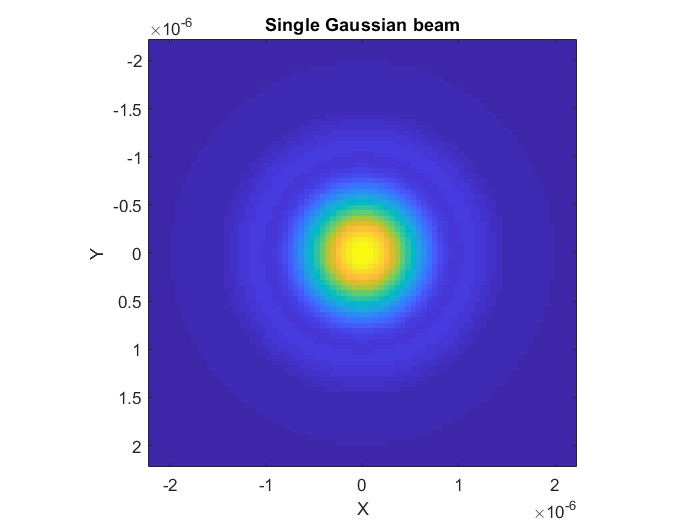

% Wavelength in medium/vacuum [m]
wavelength = 1064.0e-9;

% Setup the T-matrix object
T = ott.Tmatrix.simple('sphere', wavelength, 'index_medium', 1.0, ...
    'index_particle', 1.2, 'wavelength0', wavelength);

% Create the Gaussian beam
beam = ott.BscPmGauss('polarisation', [1 1i], 'angle_deg', 50, ...
    'index_medium', 1.0, 'wavelength0', wavelength, 'power', 0.5);

figure();
beam.visualise('axis', 'z');
title('Single Gaussian beam');

The subsequent sections will also make use of the following variables

% Displacement of beams [wavelength_medium]
displacement = 0.2*wavelength;

% Phase shift for 2nd beam
phase = exp(2*pi*1i/0.1);

% Range for force/displacement graph
x = linspace(-2, 2, 80)*wavelength;

# Coherent beams with expanded Nmax

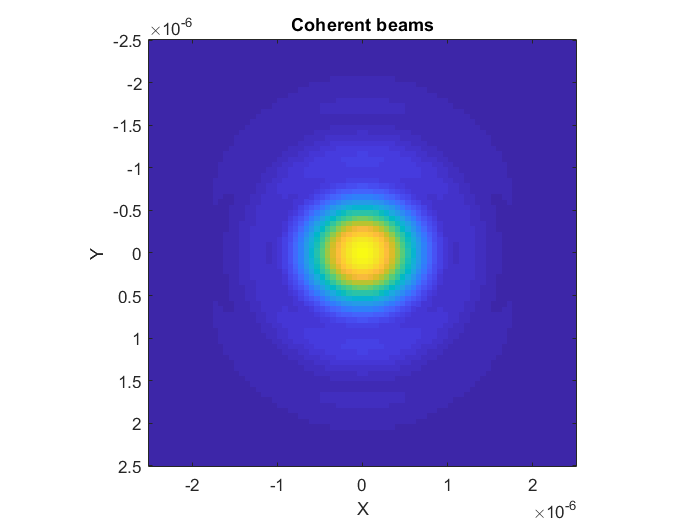


tic

% Calculate new Nmax
Nmax = ott.utils.ka2nmax(ott.utils.nmax2ka(beam.Nmax) ...
    + displacement*T.k_medium);

% Change the Nmax and create the two beams
beam1 = beam.translateXyz([-displacement; 0; 0], 'Nmax', Nmax);
beam2 = beam.translateXyz([displacement; 0; 0], 'Nmax', Nmax);

% Add the beams
nbeam = beam1 + beam2 * phase;

% Visualise the beam
figure();
nbeam.visualise('axis', 'z');
title('Coherent beams');


% Calculate the force along the x-axis
fx1 = ott.forcetorque(nbeam, T, 'position', [1;0;0] * x);

disp(['Calculation with expanded Nmax took ' num2str(toc) ' seconds']);

Calculation with expanded Nmax took 1.2335 seconds


# Coherent beams with same Nmax


tic

fx2 = zeros(3, length(x));

for ii = 1:length(x)

  % Translate and add the beams
  beam1 = beam.translateXyz([x(ii)+displacement; 0; 0]);
  beam2 = beam.translateXyz([x(ii)-displacement; 0; 0]);
  tbeam = beam1 + beam2 * phase;

  % Scatter the beam and calculate the force
  sbeam = T * tbeam;
  fx2(:, ii) = ott.forcetorque(tbeam, sbeam);
end

disp(['Calculation with same Nmax took ' num2str(toc) ' seconds']);

Calculation with same Nmax took 1.5959 seconds


# Incoherent beams


tic

fx3 = ott.forcetorque(beam, T, ...
    'position', [1;0;0] * x + [displacement; 0; 0]);
fx3 = fx3 + ott.forcetorque(beam * phase, T, ...
    'position', [1;0;0] * x - [displacement; 0; 0]);

disp(['Incoherent calculation (same Nmax) took ' num2str(toc) ' seconds']);

Incoherent calculation (same Nmax) took 1.6414 seconds


# Incoherent with expanded Nmax


tic

% Calculate new Nmax
Nmax = ott.utils.ka2nmax(ott.utils.nmax2ka(beam.Nmax) ...
    + displacement*T.k_medium);
  
% Change the Nmax and create the two beams
beam1 = beam.translateXyz([-displacement; 0; 0], 'Nmax', Nmax);
beam2 = beam.translateXyz([displacement; 0; 0], 'Nmax', Nmax);

beamc = beam1.append(beam2);

fx4 = ott.forcetorque(beamc, T, 'position', [1;0;0] * x);
fx4 = sum(fx4, 3);

disp(['Incoherent calculation (expanded Nmax) took ' num2str(toc) ' seconds']);

Incoherent calculation (expanded Nmax) took 0.95792 seconds


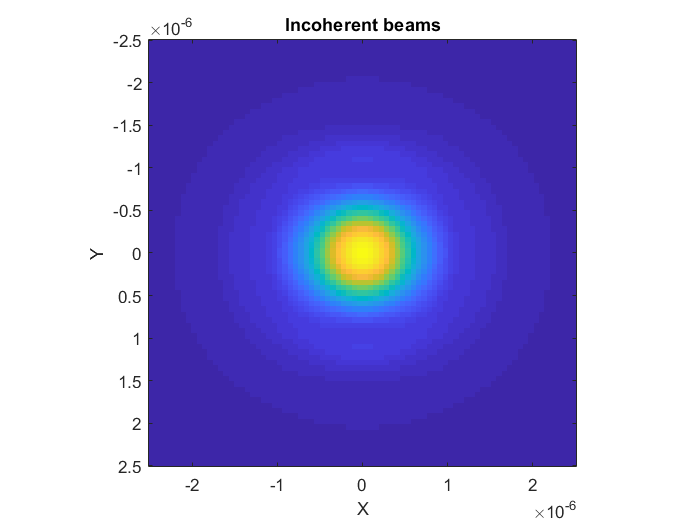


% Generate a visualisation of the beam
figure();
beamc.visualise('axis', 'z', 'combine', 'incoherent');
title('Incoherent beams');

# Generate a figure showing the force displacement graphs

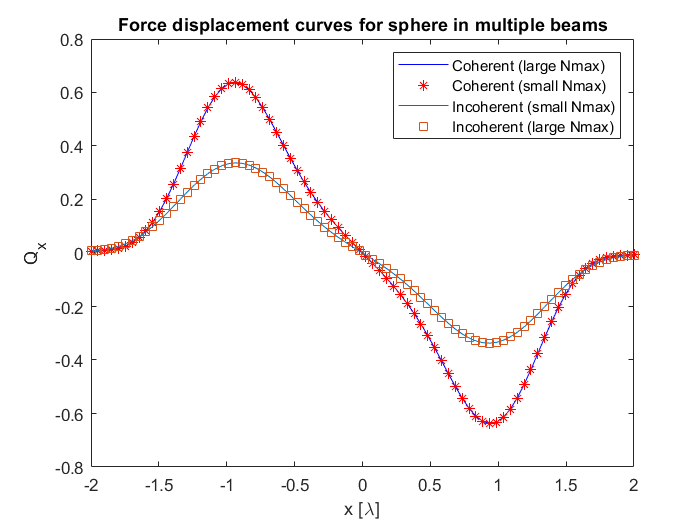

sx = x/wavelength;

figure();
plot(sx, fx1(1, :), 'b', sx, fx2(1, :), 'r*', sx, fx3(1, :), sx, fx4(1, :), 's');
legend('Coherent (large Nmax)', 'Coherent (small Nmax)', ...
    'Incoherent (small Nmax)', 'Incoherent (large Nmax)');
xlabel('x [\lambda]')
ylabel('Q_x')
title('Force displacement curves for sphere in multiple beams')

## About

This example live script is part of OTT.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/ott](https://github.com/ilent2/ott)